circ_rad = 30;
led_rad = 25;
positions = 8;
led_coords = [];
x_cent = 107.5;
y_cent = 77.5;    
for i = 1:positions
   led_coords(i,1) = x_cent + led_rad * cos(i*2*pi/positions);
   led_coords(i,2) = y_cent + led_rad * sin(i*2*pi/positions);
end
led_coords

led_coords =   125.1777   95.1777
  107.5000  102.5000
   89.8223   95.1777
   82.5000   77.5000
   89.8223   59.8223
  107.5000   52.5000
  125.1777   59.8223
  132.5000   77.5000


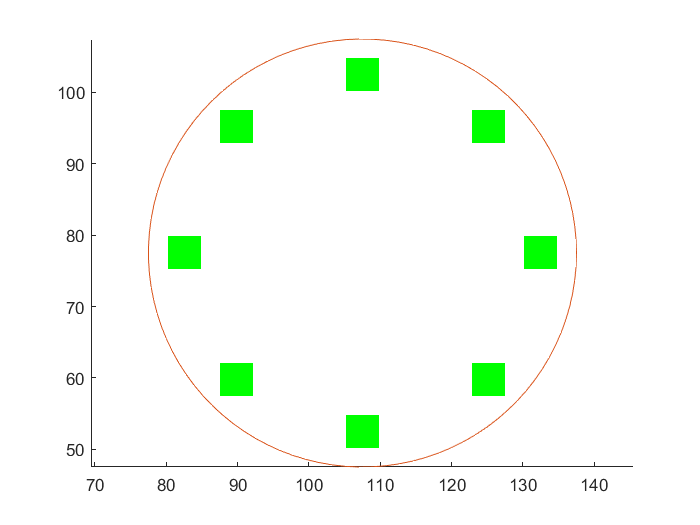

theta = linspace(0,2*pi);
perim_x = x_cent + circ_rad * cos(theta);
perim_y = y_cent + circ_rad * sin(theta);
scatter(led_coords(:,1), led_coords(:,2),'gs', 'LineWidth',15)
hold on
plot(perim_x,perim_y)
axis equal
hold off

u = symunit;
battery_capacity = 3.5*([u.A]*[u.h]);%Ah
nominal_voltage = 3.7*[u.V];
buck_efficiency = .95;
LED_power_draw = 8*5*[u.V]*.05*[u.A];%each LED draws 50mA @ 5V, source 
% https://www.pololu.com/product/2547#:~:text=Each%20RGB%20LED%20draws%20approximately%2050%20mA%20when%20it%20is,and%20powered%20at%205%20V.
ESP_power_draw = 5*[u.V] * [.070 .300]*[u.A];% assume 70-300mA current draw @ 5V (voltage is at 5V from the LDO that powers the ESP)
%https://www.esp8266.com/viewtopic.php?t=3875
battery_energy = battery_capacity*nominal_voltage;
battery_life = buck_efficiency * battery_energy ./ (LED_power_draw+ESP_power_draw) %h

$$battery\_life = \left(\begin{array}{cc} 5.2351\,h & 3.5150\,h \end{array}\right)$$

%assume all other components are negligible in power draw